## fv0 Intro

This scrip import expomential fitness as experiment data, and simulation result comes from PDE model with Reflecting boundaries |x|<=a.

This scrip just changing para by hand and make the frame of simulation.

## fv1 Intro

In this scrip, we try to adjust para automatically. First we use **gradient descent**. 

## fv4 Intro

In this scrip we try different input to get min residual.

## fv5 Intro

In this scrip, we adapt GD into steepest descent.

## fv6 Intro

In this scrip we combine fv4 and fv5.

## Import data and previewing

The data come from expomential fitness data.

data_name='n589';
selecting_curve='xy';
experiment_interval=30;
min_length=40;
time_scale=experiment_interval*(1:min_length);

fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
t=time_scale;
a(1)=5.385e+05;%n589_30s
a(2)=0.0001211;
a(3)=-3.902e+05;
a(4)=-0.006544;   

Reserved_length=min_length;
interceptive_experiment_MSD=1e-18*fun(a,time_scale);


## Main loop

residual_min=1;
range_a=13e-7:5e-8:17e-7;
range_Gamma=0.4:0.08:0.8;
range_K_gamma=1e-15:5e-15:16e-15;
total_work=length(range_a)*length(range_Gamma)*length(range_K_gamma);
progress=0;
for a=range_a
    for Gamma=range_Gamma
        for K_gamma=range_K_gamma
            input=[a,Gamma,K_gamma];
            try
                [parameter_history,residual_history]=FDE_GD_SD(experiment_interval,Reserved_length,interceptive_experiment_MSD,input);
            catch
            end
            if residual_history(end)<residual_min
                best_para=parameter_history(end,:);
                residual_min=residual_history(end);
                disp([num2str(best_para),'\',num2str(residual_min)])
            end
            progress=progress+1;
            disp(['complete ',num2str(progress),'/',num2str(total_work)])
        end
    end
end

1.3154e-06     0.65573    1.19e-15\6.3844e-24


complete 1/216


1.3515e-06     0.47759  6.3898e-15\3.9196e-24


complete 2/216


1.3682e-06     0.44589  1.1434e-14\2.3719e-24


complete 3/216


1.3712e-06     0.43022  1.6419e-14\1.5479e-24


complete 4/216
complete 5/216
complete 6/216


1.3551e-06     0.50816  1.1188e-14\1.228e-24


complete 7/216


1.3503e-06     0.49629  1.6156e-14\6.9606e-25


complete 8/216
complete 9/216
complete 10/216


1.3393e-06     0.57448   1.107e-14\5.0299e-25


complete 11/216


1.3319e-06     0.56708  1.6047e-14\2.563e-25


complete 12/216
complete 13/216
complete 14/216


1.3248e-06      0.6457  1.1019e-14\1.6698e-25


complete 15/216


1.3257e-06     0.64241  1.6007e-14\1.0237e-25


complete 16/216
complete 17/216
complete 18/216


1.3258e-06     0.72074  1.0997e-14\7.3565e-26


complete 19/216
complete 20/216
complete 21/216


1.3183e-06     0.80151  6.0006e-15\5.4923e-26


complete 22/216
complete 23/216
complete 24/216
complete 25/216
complete 26/216
complete 27/216
complete 28/216
complete 29/216
complete 30/216
complete 31/216
complete 32/216
complete 33/216
complete 34/216
complete 35/216
complete 36/216
complete 37/216
complete 38/216
complete 39/216


1.3828e-06     0.62996  1.5901e-14\4.1378e-26


complete 40/216
complete 41/216
complete 42/216


1.3692e-06     0.69657  1.0896e-14\3.3307e-26


complete 43/216
complete 44/216
complete 45/216


1.3625e-06     0.78354  5.9721e-15\1.6853e-26


complete 46/216
complete 47/216
complete 48/216
complete 49/216
complete 50/216
complete 51/216
complete 52/216
complete 53/216
complete 54/216
complete 55/216
complete 56/216
complete 57/216
complete 58/216
complete 59/216
complete 60/216
complete 61/216
complete 62/216


1.4074e-06     0.64158  1.1005e-14\1.209e-26


complete 63/216
complete 64/216
complete 65/216
complete 66/216
complete 67/216
complete 68/216
complete 69/216
complete 70/216
complete 71/216
complete 72/216
complete 73/216
complete 74/216
complete 75/216
complete 76/216
complete 77/216
complete 78/216
complete 79/216
complete 80/216
complete 81/216
complete 82/216
complete 83/216


1.457e-06     0.56154  1.6009e-14\9.4683e-27


complete 84/216
complete 85/216
complete 86/216


1.4461e-06     0.63851  1.0994e-14\4.794e-27


complete 87/216
complete 88/216
complete 89/216
complete 90/216
complete 91/216
complete 92/216
complete 93/216
complete 94/216
complete 95/216
complete 96/216
complete 97/216
complete 98/216
complete 99/216
complete 100/216
complete 101/216
complete 102/216
complete 103/216
complete 104/216
complete 105/216
complete 106/216
complete 107/216
complete 108/216
complete 109/216
complete 110/216
complete 111/216
complete 112/216
complete 113/216
complete 114/216
complete 115/216
complete 116/216
complete 117/216
complete 118/216
complete 119/216
complete 120/216
complete 121/216
complete 122/216
complete 123/216
complete 124/216
complete 125/216
complete 126/216
complete 127/216
complete 128/216
complete 129/216
complete 130/216
complete 131/216
complete 132/216
complete 133/216
complete 134/216
complete 135/216
complete 136/216
complete 137/216
complete 138/216
complete 139/216
complete 140/216
complete 141/216
complete 142/216
complete 143/216
complete 144/216
complete 145/216
complete 1

plot MSD

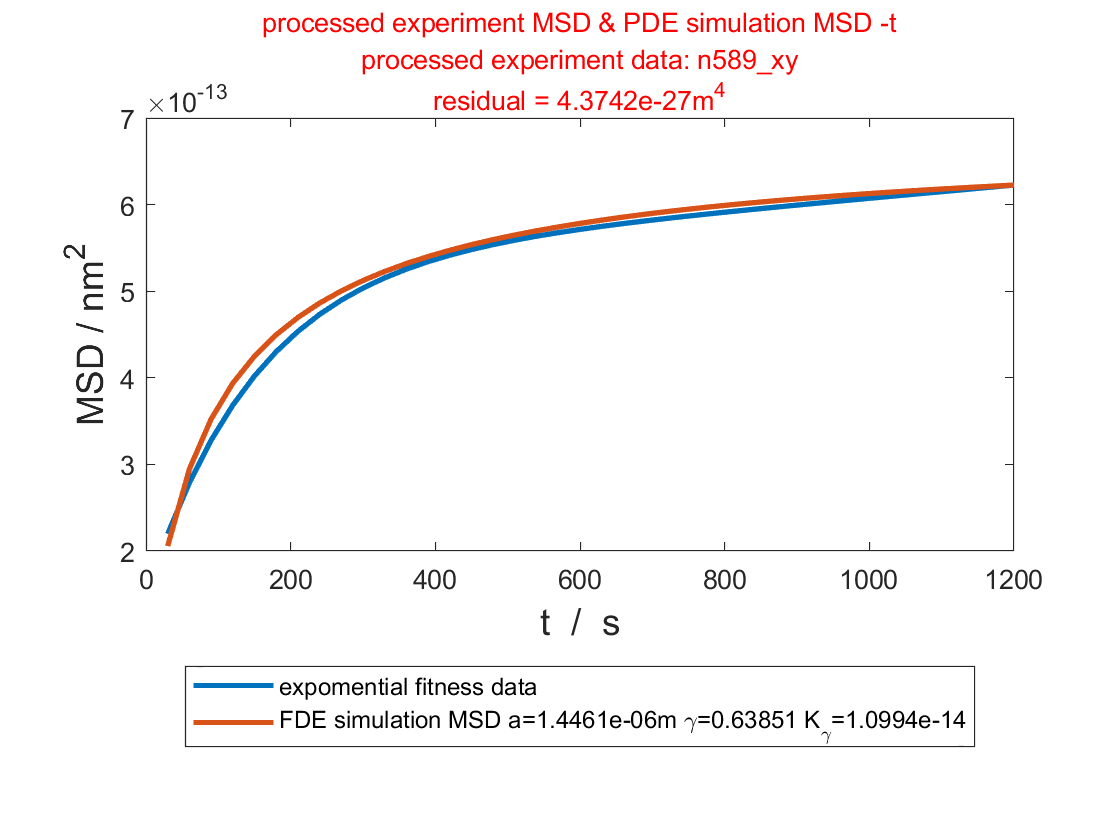

a=best_para(1);%m
Gamma=best_para(2);
K_gamma=best_para(3);


simulation_MSD=[];
for t=experiment_interval*[1:min_length]
    sum_number=10;
    sum_list=zeros(sum_number,1);
    for m=1:sum_number
        sum_list(m)=((-1)^m/m^2)*mlf(Gamma,1,-K_gamma*m^2*pi^2/a^2*t^Gamma,6);
    end
    simulation_MSD=[simulation_MSD,a^2*(1/3+4/pi^2*sum(sum_list))];
end
residual=sum((interceptive_experiment_MSD-simulation_MSD).^2);

figure
plot(time_scale,interceptive_experiment_MSD,"LineWidth",2,'displayname','expomential fitness data')
hold on
legend_name=strcat('FDE simulation MSD',' a= ',num2str(a),'m \gamma=',num2str(Gamma),' K_\gamma= ',num2str(K_gamma));
plot(time_scale,simulation_MSD,"LineWidth",2,'displayname',legend_name)
xlabel('t  /  s','FontSize',14);
ylabel('MSD / nm^2','FontSize',14);
title({['processed experiment MSD & PDE simulation MSD -t'],['processed experiment data: ',strrep(data_name,'_','\_'),'\_',selecting_curve],['residual = ',num2str(residual),'m^4']},'Color','r','FontSize',10);
legend('Location','southoutside');

## SD Parameter importing

a=best_para(1);%m
Gamma=best_para(2);
K_gamma=best_para(3);

% decide step length and sample length (proportional)

step_length=1/20;
sample_length=1/10000;

## SD storage system

% add parameter history and gradient history
parameter_history=[a,Gamma,K_gamma];
gradient_history=[];
residual_history=[];

## SD Main loop

for step_number=1:100
    residual_0=FDE_get_residual(interceptive_experiment_MSD,a,Gamma,K_gamma,experiment_interval,min_length);
    residual_a=FDE_get_residual(interceptive_experiment_MSD,a*(1+sample_length),Gamma,K_gamma,experiment_interval,min_length);
    residual_Gamma=FDE_get_residual(interceptive_experiment_MSD,a,Gamma*(1+sample_length),K_gamma,experiment_interval,min_length);
    residual_K=FDE_get_residual(interceptive_experiment_MSD,a,Gamma,K_gamma*(1+sample_length),experiment_interval,min_length);
    gradient=[residual_a-residual_0,residual_Gamma-residual_0,residual_K-residual_0]/sample_length;
    unit_gradient=gradient/norm(gradient);
    if step_number==1
        standard_gradient=norm(gradient);
    end
    
    %por=norm(gradient)/standard_gradient;
    por=residual_0/norm(gradient);
    a=a*(1-unit_gradient(1)*step_length*por);
    Gamma=Gamma*(1-unit_gradient(2)*step_length*por);
    K_gamma=K_gamma*(1-unit_gradient(3)*step_length*por);
    
    parameter_history=[parameter_history;[a,Gamma,K_gamma]];
    gradient_history=[gradient_history;gradient];
    residual_history=[residual_history;residual_0];
end

## SD saving

saving data

%saving_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.02图像';
%save([saving_location,'\data\history data N=',num2str(Total_experiment_number),' step=',num2str(step_length),datestr(now,' yyyy-mm-dd HH'),'.mat'],'parameter_history','gradient_history','residual_history')

Plot and plot saving: gradient history

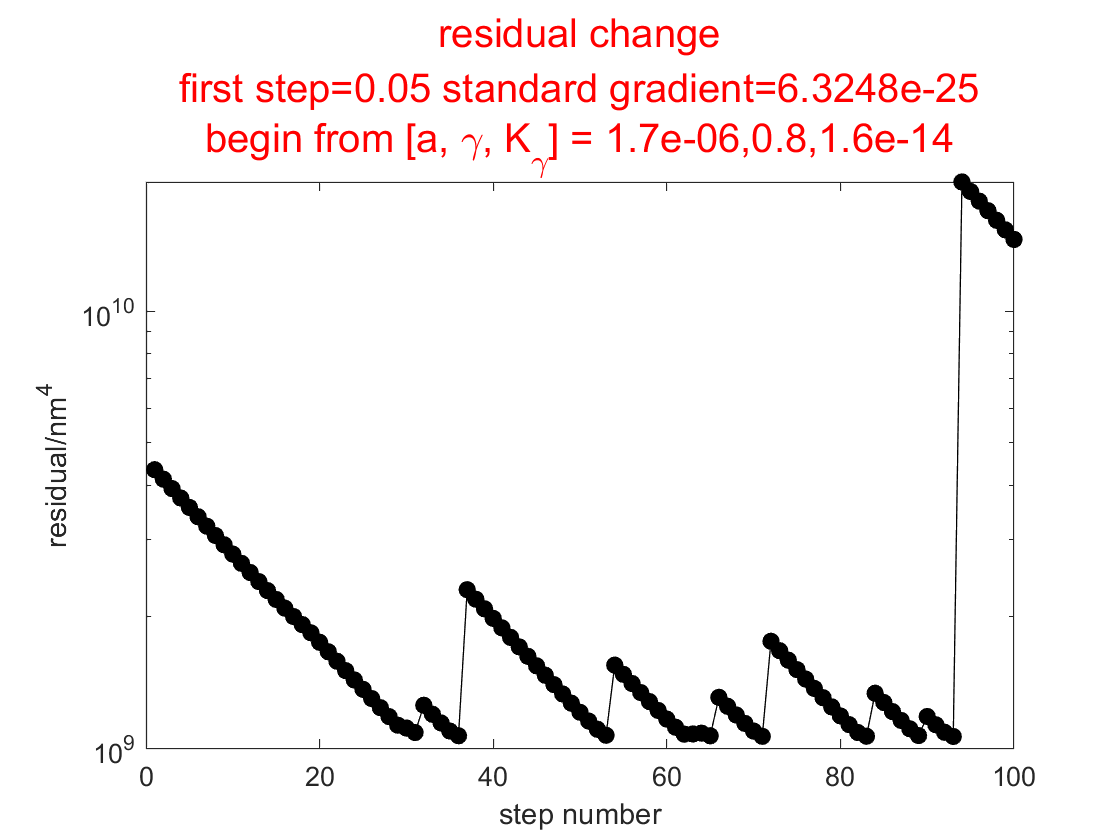

figure
plot((residual_history(:,1))*1e36,'k-o','MarkerFaceColor','k')
xlabel('step number')
ylabel('residual/nm^4')
set(gca,'yscale','log');
title({'residual change',['first step=',num2str(step_length),' standard gradient=',num2str(standard_gradient)],['begin from [a, \gamma, K_\gamma] = ',num2str(input(1)),',',num2str(input(2)),',',num2str(input(3))]},'Color','r','FontSize',15)

plot MSD

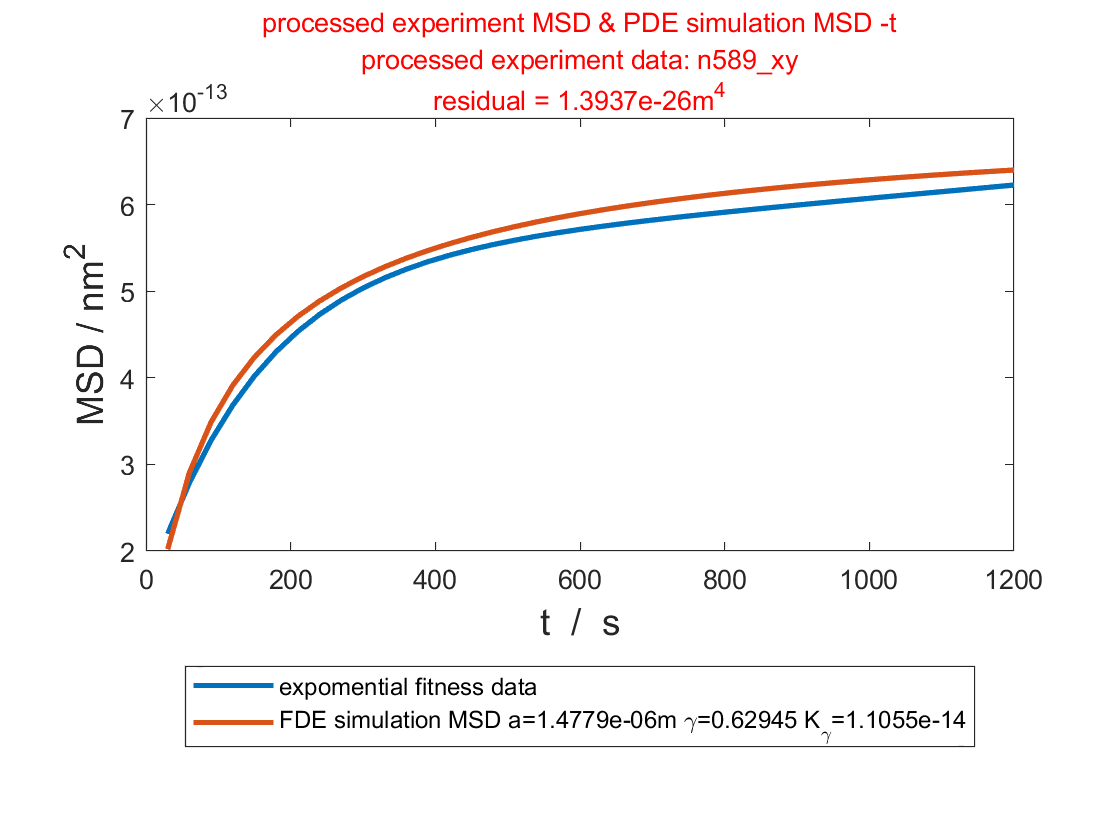

a=parameter_history(end,1);%m
Gamma=parameter_history(end,2);
K_gamma=parameter_history(end,3);


simulation_MSD=[];
for t=experiment_interval*[1:min_length]
    sum_number=10;
    sum_list=zeros(sum_number,1);
    for m=1:sum_number
        sum_list(m)=((-1)^m/m^2)*mlf(Gamma,1,-K_gamma*m^2*pi^2/a^2*t^Gamma,6);
    end
    simulation_MSD=[simulation_MSD,a^2*(1/3+4/pi^2*sum(sum_list))];
end
residual=sum((interceptive_experiment_MSD-simulation_MSD).^2);

figure
plot(time_scale,interceptive_experiment_MSD,"LineWidth",2,'displayname','expomential fitness data')
hold on
legend_name=strcat('FDE simulation MSD',' a= ',num2str(a),'m \gamma=',num2str(Gamma),' K_\gamma= ',num2str(K_gamma));
plot(time_scale,simulation_MSD,"LineWidth",2,'displayname',legend_name)
xlabel('t  /  s','FontSize',14);
ylabel('MSD / nm^2','FontSize',14);
title({['processed experiment MSD & PDE simulation MSD -t'],['processed experiment data: ',strrep(data_name,'_','\_'),'\_',selecting_curve],['residual = ',num2str(residual),'m^4']},'Color','r','FontSize',10);
legend('Location','southoutside');